# QEA 3 Solar House Project

Meagan Martin and Myles Lack-Zell

10/7/21

% System variables
% tt=[0.01:0.01:0.3]; % tile thickness [m] (redundant)
% It=[0.1:0.05:0.5]; % insulation thickness [m] (redundant)
Aw=13; % window area [m^2]
AiIn=99.6; % inner surface area of insulation [m^2]
Ai=AiIn; % cross-sectional area of insulation for conduction [m^2] (neglecting corners and control)
hIn=15; % inside convective heat transfer coefficient [W/(m^2*K)]
hOut=30; % outside convective heat transfer coefficient [W/(m^2*K)]
hEq=0.7; % equivalent heat transfer coefficient through window [W/(m^2*K)]
k_i=0.04; % insulation (fiberglass) thermal conductivity [W/(m*K)]

% tile variables
tDensity=3000; % tile density [kg/m^3]
tSpecific=300; % tile specific heat [J/(kg*K)]

% initial conditions
T_aOut=-3+273.15; % outside air temperature (constant) [K] (-3 [°C])
T0=-3+273.15; % initial tile temperature [K] (-3 [°C])

% single run to test
tt=0.01; It=0.1;

% tile heat capacity calculations
tVol=5.1*5*tt; % tile density [m^3]
tMass=tVol*tDensity; % tile mass [kg]
Ct=tMass*tSpecific; % tile heat capacity [J/K]

%calculate thermal resistances and run ode45, then save in a matrix
At=51+20.2*tt; % tile surface area [m^2]
AiOut=108.6+5*It; % outer surface area of insulation [m^2]

R_t_aIn = 1/(hIn*At); % Thermal Resistance (conv) b/w tile and internal air [K/W]
R_aIn_i = 1/(hIn*Ai); % Thermal Resistance (conv) b/w internal air and walls [K/W]
R_i = It/(k_i*Ai); % Thermal Resistance (cond) through insolation [K/W]
R_i_aOut = 1./(hOut*AiOut); % Thermal Resistance (conv) from insolation to outside air [K/W]
R_aIn_w = 1/(hIn*Aw); % Thermal Resistance (conv) of internal air to window [K/W]
R_w = 1/(hEq*Aw); % Thermal Resistance of window [K/W]
R_w_aOut = 1/(hOut*Aw); % Thermal Resistance (conv) fromm window to outside air [K/W]

% solve differential equations (FUNCTION 'tempFun' AT END OF DOCUMENT)
tspan=[0,24*3600]; % time span [s] (24 [h])
[t,Tt]=ode45(@(t,Tt) tempFun(t,Tt,tt,It,Aw,Ct,T_aOut,R_t_aIn,R_aIn_i,R_i,R_i_aOut,R_aIn_w,R_w,R_w_aOut),tspan,T0); % solve equation for floor temp [K]

% looping through to solve
for It=0.1:0.05:0.5 % cycle through insulation thicknesses of 0.1-0.5 [m] in 0.05 [m] increments
    for tt=0.01:0.01:0.3 % cycle through tile thicknesses of 0.01-0.3 [m] in increments of 0.01 [m]
        % tile heat capacity calculations
        tVol=5.1*5*tt; % tile density [m^3]
        tMass=tVol*tDensity; % tile mass [kg]
        Ct=tMass*tSpecific; % tile heat capacity [J/K]
        
        %calculate thermal resistances and run ode45, then save in a matrix
        At=51+20.2*tt; % tile surface area [m^2]
        AiOut=108.6+5*It; % outer surface area of insulation [m^2]
        
        R_t_aIn = 1/(hIn*At); % Thermal Resistance (conv) b/w tile and internal air [K/W]
        R_aIn_i = 1/(hIn*Ai); % Thermal Resistance (conv) b/w internal air and walls [K/W]
        R_i = It/(k_i*Ai); % Thermal Resistance (cond) through insolation [K/W]
        R_i_aOut = 1./(hOut*AiOut); % Thermal Resistance (conv) from insolation to outside air [K/W]
        R_aIn_w = 1/(hIn*Aw); % Thermal Resistance (conv) of internal air to window [K/W]
        R_w = 1/(hEq*Aw); % Thermal Resistance of window [K/W]
        R_w_aOut = 1/(hOut*Aw); % Thermal Resistance (conv) fromm window to outside air [K/W]
        
        % solve differential equations (FUNCTION 'tempFun' AT END OF DOCUMENT)
        tspan=[0,24*3600]; % time span [s] (24 [h])
        Temps(i_n,[t,Tt]=ode45(@(t,Tt) tempFun(t,Tt,tt,It,Aw,Ct,T_aOut,R_t_aIn,R_aIn_i,R_i,R_i_aOut,R_aIn_w,R_w,R_w_aOut),tspan,T0); % solve equation for floor temp [K]
    end
end

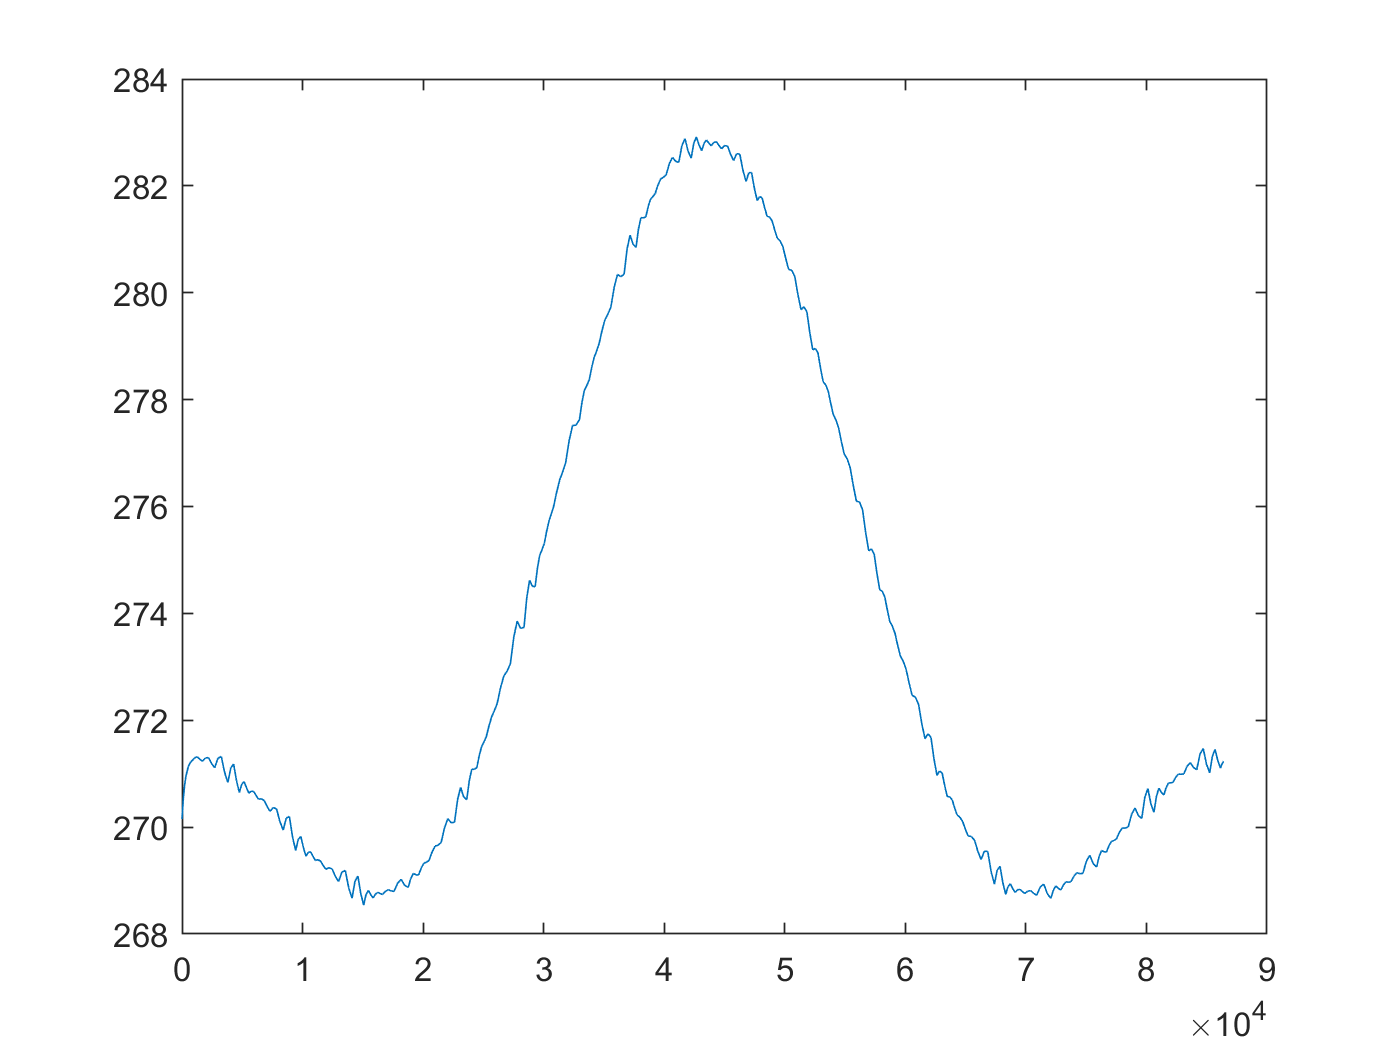

% plot
figure()
%hold on
plot(t,Tt)

function dTdt = tempFun(t,Tt,tt,It,Aw,Ct,T_aOut,R_t_aIn,R_aIn_i,R_i,R_i_aOut,R_aIn_w,R_w,R_w_aOut) % add input variables (tt=tile thickness, It=insulation thickness)
    % time-dependent variables
    qW=-361*cos((pi*t)/(12*3600))+224*cos((pi*t)/(6*3600))+210; % temp gradient perpendicular to window
    QdotIn=Aw*qW; % heat transfer rate into house through by solar radiation [W]
    
    QdotOut=(Tt-T_aOut)*((1/(R_t_aIn))+(1/(R_aIn_i+R_i+R_i_aOut))+(1/(R_aIn_w+R_w+R_w_aOut)));
        % heat transfer rate from tile to outside air [W]
    
    % ode
    dTdt=QdotIn/Ct-QdotOut/Ct; % tile temperature derivative
end